clear;
syms x [2,1]
syms xhat [2,1]
syms t
a0 = 1;
beta0 = 1;
gamma=1;
% sat = @(u)min(1,max(-1,u));
a = 1;
symmin =  @(x,y)feval(symengine,'min',x,y);
symmax =  @(x,y)feval(symengine,'max',x,y);
s(x1,x2) =symmin(1,symmax((gamma*x1+x2)/0.1,-1)) ;
u(x1,x2) = symmin(2,symmax((-(gamma.*abs(x2)./(0.5.*cos(x1))+tan(x1)+1).*s(x1,x2)),-2));
% u(xhat1,xhat2) = symmin(2,symmax((-(a.*abs(xhat2)./(0.5.*cos(xhat1))+tan(xhat1)+beta0).*s(xhat1,xhat2)),-2));
f(x1,x2) = [x2;a0 * (sin(x1) + u(x1,x2) * cos(x1))];
h(x1) = x1;% + 0.05*sin(20*t);
% A = jacobian(f,x);
% A = A(xhat1,xhat2);
A= [0 1;0.5*cos(xhat1)  0];
C = [1,0];

syms P [2,2]
P=(P+P')/2; % to ensure that P is symmetric
Q = 3*eye(2);
R = 1;
dP = A*P+P*A'+Q-P*C'/R*C*P;
dPv = reshape(dP,4,1);% vectorizing
H = P*C'/R;
fhat(t,xhat1,xhat2,x1) = f(xhat1,xhat2)+H*(x1-h(xhat1));
F = matlabFunction([f(x1,x2);fhat(t,xhat1,xhat2,x1);dPv],'Vars',{t,[x1;x2;xhat1;xhat2;P1_1;P1_2;P2_1;P2_2]});
x0 = [pi/6;0];
P0 = 30*eye(2);
xhat0 = [0;0];
X0 = [x0;xhat0;P0(:)];
tf = 20;
t=linspace(0,tf,200);
options = odeset('OutputFcn','odeplot','OutputSel',1:4);
figure(5);
sol=ode45(F,[0,tf],X0,options);

### Task 2  

### EKF

### Question (1) 

 Assume that only the position is measured and not the velocity. The measured output also has a disturbance:y=x1+0.05sin20t

Design and tune an Extended Kalman Filter to estimate the states x^(t) from the input u and the measured output y. In this first step you should use feedback from the true states in the sliding mode controller u(x). Plot the true states x(t) together with the estimated states x^(t), when the system is started at x1(0)=π/6 and x2(0)=0, and x^1(0)=0 andx^2(0)=0.

### **Solution: **

Equation Derivative

(1)$\begin{cases}
\dot x =x_2
\\ \dot x_2=a(\sin x+u\cos x_1
)
\end{cases}$

(2)$A=\frac{df}{dx}=\left[ \begin{array}{cc} 0 & 1\\ a*\cos x_1& 0 \end{array} \right]$

(3) $C=[1, 0]$

(4) $H(t)=P(t )* C^T*R^{-1
}$

(5)$dP=AP+PA^{T}+Q-PC^TR^{-1}CP, P(0)=P_0$

(6) $\dot {\tilde{x}}= f(\hat{x},u)+H(t)(y-h(\hat{x})), \hat{x(0)}=\tilde{x_0}$

The initial state was set as


$$x_1(0)=\pi/6;x_2(0)=0; \hat{x_1}(0)=0; \hat{x_2}(0)=0;$$


*a* is set as 1 for the true and EKF system. The simulation results are shown as below. From figure 5 we can see that there is a difference between the estimated state and true state at the intial state, while the estimated state can follow the true state after about 1 sec. It can be verified that the designed estimating algorithm is efficient.

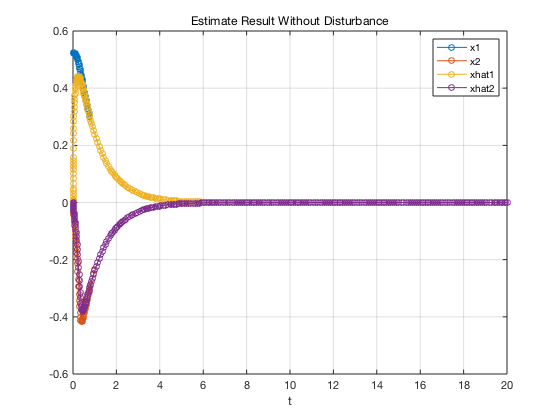

xlabel('t')
legend('x1','x2','xhat1','xhat2') 
title('Estimate Result Without Disturbance')
grid on

**Figure 5.  a=1 for EKF and true system**

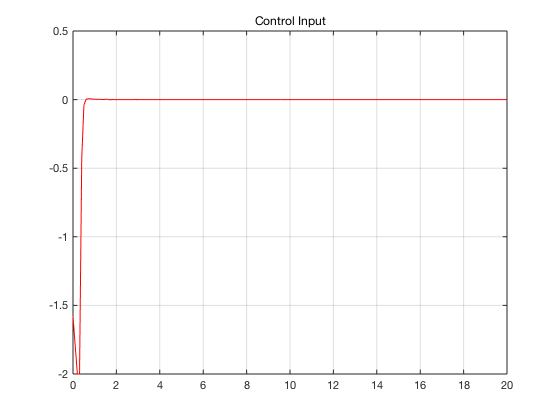

x=deval(sol,t);
sat=@(u)min(1,max(-1,u));
% u=((1./(a*cos(x(1,:))).*(-gamma.*x(2,:)-a*sin(x(1,:)))-1).*sat((gamma*x(1,:)+x(2,:))./0.1));
u= min(2,max((-(gamma.*abs(x(2,:))./(0.5.*cos(x(1,:)))+tan(x(1,:))+1).*s(x(1,:),x(2,:))),-2));

figure(6)
plot(t,u,'-r')
title('Control Input')
grid on

**Figure 6. Control input of the true system**

### Question (2)  

Now use your EKF together with the sliding mode control, i.e., use u(x^). Simulate the system including the measurement disturbance. For the “true” system, use a=1. For the model in the EKF, use a=0.5, a=1 and a=1.5. Compare and discuss the result.

### Solution :

Result Analysis of the role of parameter *a*:

a is set as 1 a for true system and EKF system in figure 7. The measured state x1 was added a disturbance.  From figure 7 we can see that the estimated state has a similar trend with the last reults(with disturbance), but the estimated has more vibration compared due to the disturbance.  By changing the value of a in EKF system, the estimated state experienced a greatly different trend. In the following figure, Figure 8 is the result of *a*=0.5 in EKF system and figure 9 is the reuslt of a=1.5 in EKF system.  By comparing these results, we can see that with the increase of a the amplitude of estimated state $\hat{x2}$ before stable state is achieved will also increase,  which is caused by the model error, so we can conclude that the model accuracy has a great influence on the estimation accuracy.

### For a =1 in EKF

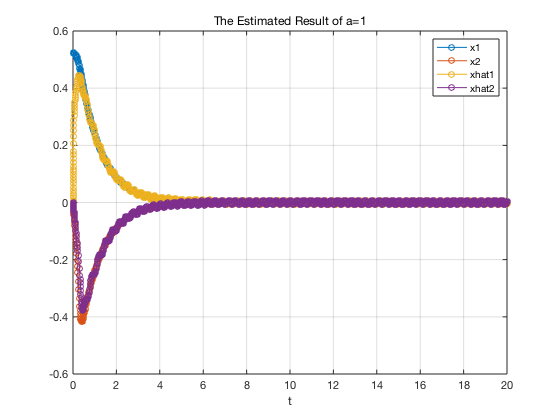

 

% % Compare Between the true modle and EKF Bsed Control
syms x [2,1]
syms xhat [6,1]
% syms xhat1 [2,1]
% syms xhat2 [2,1]
syms t
a = 1;
a1=0.5;
a2=1.5;
beta0 = 1;
gamma=1;
symmin =  @(x,y)feval(symengine,'min',x,y);
symmax =  @(x,y)feval(symengine,'max',x,y);

%a=1 
s(x1,x2) =symmin(1,symmax((gamma*x1+x2)/0.1,-1)) ;
u(x1,x2) = symmin(2,symmax((-(gamma.*abs(x2)./(0.5.*cos(x1))+tan(x1)+1).*s(x1,x2)),-2));
f(x1,x2) = [x2;a * (sin(x1) + u(x1,x2) * cos(x1))];

%a=0.5
% s1(x1,x2) =symmin(1,symmax((a1*x1+x2)/0.1,-1)) ;
u1(x1,x2) = symmin(2,symmax((-(gamma.*abs(x2)./(0.5.*cos(x1))+tan(x1)+1).*s(x1,x2)),-2));
f1(x1,x2) = [x2;a1 * (sin(x1) + u1(x1,x2) * cos(x1))];

%a=1.5
% s2(x1,x2) =symmin(1,symmax((a2*x1+x2)/0.1,-1)) ;
u2(x1,x2) = symmin(2,symmax((-(gamma.*abs(x2)./(0.5.*cos(x1))+tan(x1)+1).*s(x1,x2)),-2));
f2(x1,x2) = [x2;a2 * (sin(x1) + u2(x1,x2) * cos(x1))];


h(x1,t) = x1 + 0.05*sin(20*t);
A= [0 1;1*cos(x1)  0];
C = [1,0];

syms P [2,2]
P=(P+P')/2; % to ensure that P is symmetric
Q = 3*eye(2);
R = 1;
dP = A*P+P*A'+Q-P*C'/R*C*P;
dPv = reshape(dP,4,1);% vectorizing
H = P*C'/R;

%a=1
fhat(t,xhat1,xhat2,x1) = f(xhat1,xhat2)+H*(x1-h(xhat1,t));
F = matlabFunction([f(x1,x2);fhat(t,xhat1,xhat2,x1);dPv],'Vars',{t,[x1;x2;xhat1;xhat2;P1_1;P1_2;P2_1;P2_2]});
x0 = [pi/6;0];
P0 = 30*eye(2);
xhat0 = [0;0];
X0 = [x0;xhat0;P0(:)];
tf = 20;
t=linspace(0,tf,200);
options = odeset('OutputFcn','odeplot','OutputSel',1:4);
figure(7);
sol=ode45(F,[0,tf],X0,options);
xlabel('t')
legend('x1','x2','xhat1','xhat2') 
title('The Estimated Result of a=1')
grid on

**Figure 7. a=1 for true system and  EKF with disturbance**

### For a=0.5 in EKF

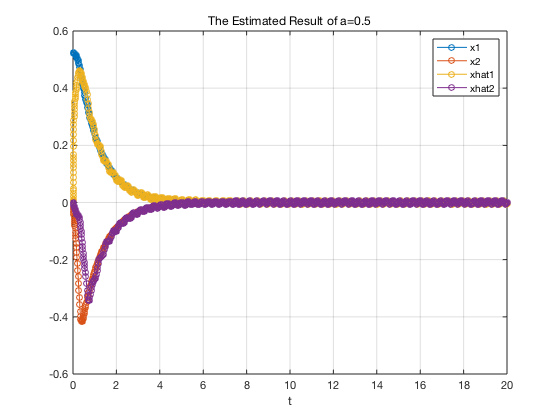

%%      a=0.5
syms x [2,1]
syms xhat [6,1]
% syms xhat1 [2,1]
% syms xhat2 [2,1]
syms t
a = 1;
a1=0.5;
a2=1.5;
beta0 = 1;
gamma=1;
symmin =  @(x,y)feval(symengine,'min',x,y);
symmax =  @(x,y)feval(symengine,'max',x,y);

%a=1 
s(x1,x2) =symmin(1,symmax((gamma*x1+x2)/0.1,-1)) ;
u(x1,x2) = symmin(2,symmax((-(gamma.*abs(x2)./(0.5.*cos(x1))+tan(x1)+1).*s(x1,x2)),-2));
f(x1,x2) = [x2;a * (sin(x1) + u(x1,x2) * cos(x1))];

%a=0.5
% s1(x1,x2) =symmin(1,symmax((a1*x1+x2)/0.1,-1)) ;
u1(x1,x2) = symmin(2,symmax((-(gamma.*abs(x2)./(0.5.*cos(x1))+tan(x1)+1).*s(x1,x2)),-2));
f1(x1,x2) = [x2;a1 * (sin(x1) + u1(x1,x2) * cos(x1))];

%a=1.5
% s2(x1,x2) =symmin(1,symmax((a2*x1+x2)/0.1,-1)) ;
u2(x1,x2) = symmin(2,symmax((-(gamma.*abs(x2)./(0.5.*cos(x1))+tan(x1)+1).*s(x1,x2)),-2));
f2(x1,x2) = [x2;a2 * (sin(x1) + u2(x1,x2) * cos(x1))];


h(x1,t) = x1 + 0.05*sin(20*t);
A= [0 1;0.5*cos(xhat1)  0];
C = [1,0];

syms P [2,2]
P=(P+P')/2; % to ensure that P is symmetric
Q = 3*eye(2);
R = 1;
dP = A*P+P*A'+Q-P*C'/R*C*P;
dPv = reshape(dP,4,1);% vectorizing
H = P*C'/R;

%a=1
fhat(t,xhat1,xhat2,x1) = f1(xhat1,xhat2)+H*(x1-h(xhat1,t));
F = matlabFunction([f(x1,x2);fhat(t,xhat1,xhat2,x1);dPv],'Vars',{t,[x1;x2;xhat1;xhat2;P1_1;P1_2;P2_1;P2_2]});
x0 = [pi/6;0];
P0 = 30*eye(2);
xhat0 = [0;0];
X0 = [x0;xhat0;P0(:)];
tf = 20;
t=linspace(0,tf,200);
options = odeset('OutputFcn','odeplot','OutputSel',1:4);

figure(8)
sol=ode45(F,[0,tf],X0,options);
xlabel('t')
legend('x1','x2','xhat1','xhat2') 
title('The Estimated Result of a=0.5')
grid on

**Figure 8. a=1 for true system and and a=0.5 for EKF with disturbance**

### **For a=1.5 in EKF**

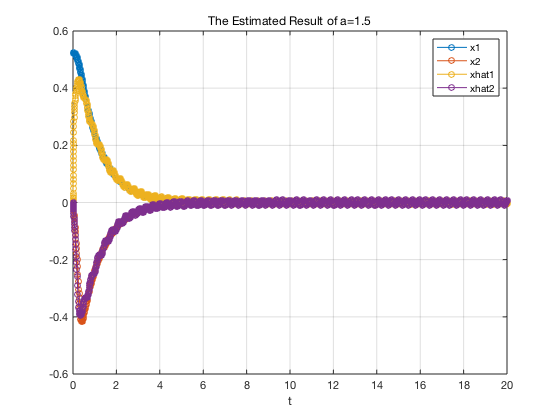

%%      a=1.5
syms x [2,1]
syms xhat [6,1]
% syms xhat1 [2,1]
% syms xhat2 [2,1]
syms t
a = 1;
a1=0.5;
a2=1.5;
beta0 = 1;
gamma=1;
symmin =  @(x,y)feval(symengine,'min',x,y);
symmax =  @(x,y)feval(symengine,'max',x,y);

%a=1 
s(x1,x2) =symmin(1,symmax((gamma*x1+x2)/0.1,-1)) ;
u(x1,x2) = symmin(2,symmax((-(gamma.*abs(x2)./(0.5.*cos(x1))+tan(x1)+1).*s(x1,x2)),-2));
f(x1,x2) = [x2;a * (sin(x1) + u(x1,x2) * cos(x1))];

%a=0.5
% s1(x1,x2) =symmin(1,symmax((a1*x1+x2)/0.1,-1)) ;
u1(x1,x2) = symmin(2,symmax((-(gamma.*abs(x2)./(0.5.*cos(x1))+tan(x1)+1).*s(x1,x2)),-2));
f1(x1,x2) = [x2;a1 * (sin(x1) + u1(x1,x2) * cos(x1))];

%a=1.5
% s2(x1,x2) =symmin(1,symmax((a2*x1+x2)/0.1,-1)) ;
u2(x1,x2) = symmin(2,symmax((-(gamma.*abs(x2)./(0.5.*cos(x1))+tan(x1)+1).*s(x1,x2)),-2));
f2(x1,x2) = [x2;a2 * (sin(x1) + u2(x1,x2) * cos(x1))];


h(x1,t) = x1 + 0.05*sin(20*t);
A= [0 1;1.5*cos(xhat1)  0];
C = [1,0];

syms P [2,2]
P=(P+P')/2; % to ensure that P is symmetric
Q = 3*eye(2);
R = 1;
dP = A*P+P*A'+Q-P*C'/R*C*P;
dPv = reshape(dP,4,1);% vectorizing
H = P*C'/R;

%a=1
fhat(t,xhat1,xhat2,x1) = f2(xhat1,xhat2)+H*(x1-h(xhat1,t));
F = matlabFunction([f(x1,x2);fhat(t,xhat1,xhat2,x1);dPv],'Vars',{t,[x1;x2;xhat1;xhat2;P1_1;P1_2;P2_1;P2_2]});
x0 = [pi/6;0];
P0 = 30*eye(2);
xhat0 = [0;0];
X0 = [x0;xhat0;P0(:)];
tf = 20;
t=linspace(0,tf,200);
options = odeset('OutputFcn','odeplot','OutputSel',1:4);

figure()
sol=ode45(F,[0,tf],X0,options);
xlabel('t')
legend('x1','x2','xhat1','xhat2') 
title('The Estimated Result of a=1.5')
grid on

**Figure 9.  a=1 for true system and and a=1.5 for EKF with disturbance**